% this script has test cases to help you test my_imfilter() which you will
% write. You should verify that you get reasonable output here before using
% your filtering to construct a hybrid image in proj1.m. The outputs are
% all saved and you can include them in your writeup. You can add calls to
% imfilter() if you want to check that my_imfilter() is doing something
% similar.
close all

## Setup

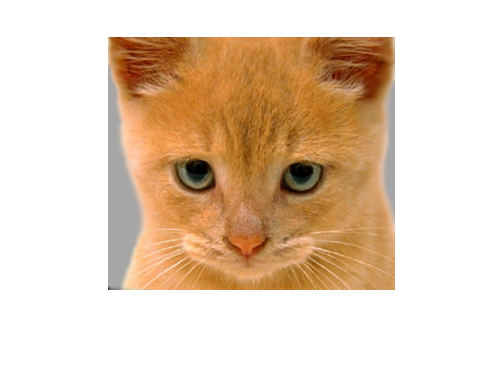

test_image = im2single(imread('../data/cat.bmp'));
test_image = imresize(test_image, 0.7, 'bilinear'); %resizing to speed up testing
figure(1)
imshow(test_image)

## Identify filter

%This filter should do nothing regardless of the padding method you use.
identity_filter = [0 0 0; 0 1 0; 0 0 0];

identity_image  = my_imfilter(test_image, identity_filter);

figure(2); imshow(identity_image);

imwrite(identity_image, 'identity_image.jpg', 'quality', 95);

## Small blur with a box filter

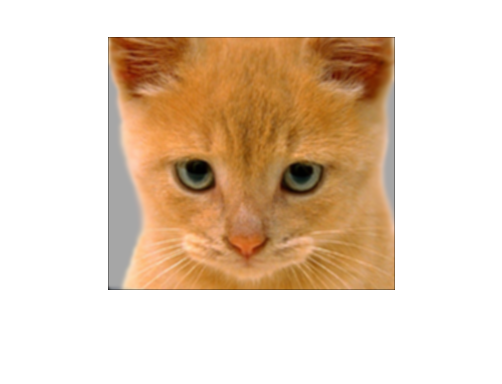

%This filter should remove some high frequencies
blur_filter = [1 1 1; 1 1 1; 1 1 1];
blur_filter = blur_filter / sum(sum(blur_filter)); %making the filter sum to 1

blur_image = my_imfilter(test_image, blur_filter);

figure(3); imshow(blur_image);

imwrite(blur_image, 'blur_image.jpg', 'quality', 95);

## Large blur

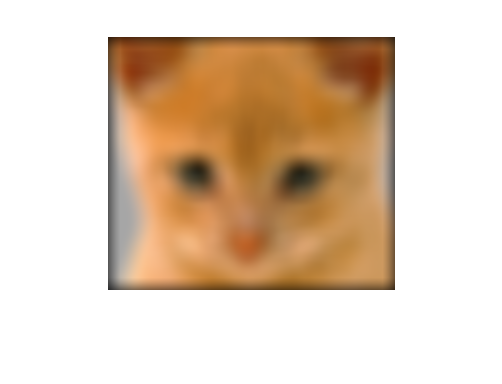

%This blur would be slow to do directly, so we instead use the fact that
%Gaussian blurs are separable and blur sequentially in each direction.
large_1d_blur_filter = fspecial('Gaussian', [25 1], 10);

large_blur_image = my_imfilter(test_image, large_1d_blur_filter);
large_blur_image = my_imfilter(large_blur_image, large_1d_blur_filter'); %notice the ' operator which transposes the filter

figure(4); imshow(large_blur_image);

imwrite(large_blur_image, 'large_blur_image.jpg', 'quality', 95);

% %If you want to see how slow this would be to do naively, try out this
% %equivalent operation:
% tic %tic and toc run a timer and then print the elapsted time
% large_blur_filter = fspecial('Gaussian', [25 25], 10);
% large_blur_image = my_imfilter(test_image, large_blur_filter);
% toc

## Oriented filter (Sobel Operator)

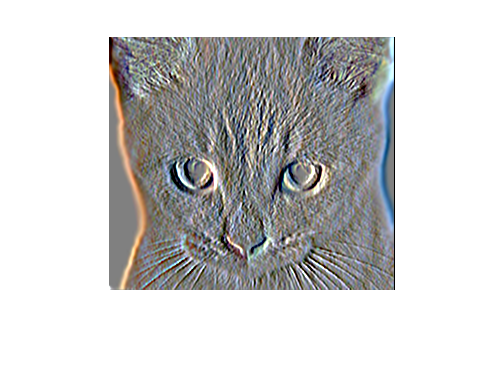

sobel_filter = [-1 0 1; -2 0 2; -1 0 1]; %should respond to horizontal gradients

sobel_image = my_imfilter(test_image, sobel_filter);

%0.5 added because the output image is centered around zero otherwise and mostly black
figure(5); imshow(sobel_image + 0.5);

imwrite(sobel_image + 0.5, 'sobel_image.jpg', 'quality', 95);

## High pass filter (Discrete Laplacian)

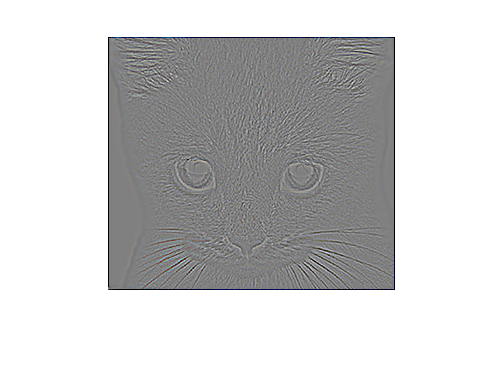

laplacian_filter = [0 1 0; 1 -4 1; 0 1 0];

laplacian_image = my_imfilter(test_image, laplacian_filter);

%0.5 added because the output image is centered around zero otherwise and mostly black
figure(6); imshow(laplacian_image + 0.5);

imwrite(laplacian_image + 0.5, 'laplacian_image.jpg', 'quality', 95);

## High pass "filter" alternative

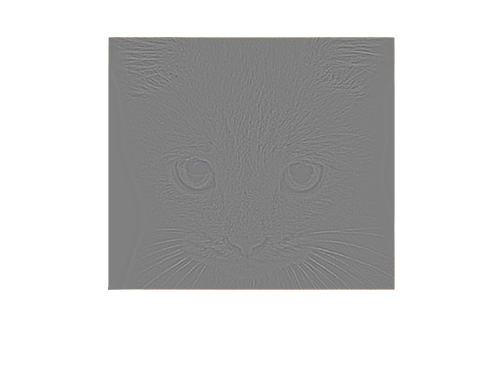

high_pass_image = test_image - blur_image; %simply subtract the low frequency content

figure(7); imshow(high_pass_image + 0.5);

imwrite(high_pass_image + 0.5, 'high_pass_image.jpg', 'quality', 95);

%by James Hays